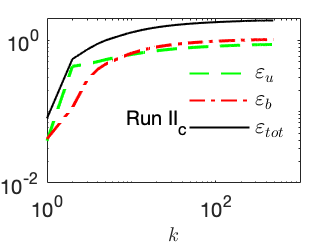

%%figure 2
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])

ylim([-0.1 1.1]);
set(gcf,'WindowStyle','normal')
xlabel('$\tau$','FontSize',11,'Interpreter','latex')
set(findall(gca, 'Type', 'Line'),'LineWidth',1.1);
xlim([0 0.07])
legend boxoff;

%


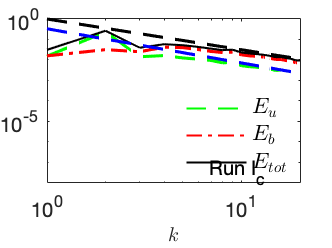

%spectrum
fig = gcf;
clear title xlabel ylabel legend
loglog(speceavr, 'g--');hold on;loglog(specbavr,'r-.');loglog(spectot,'k');loglog(testy1,'b--');loglog(testy2,'k--');hold off;
legend_handle=legend('{$E_u$}','{$E_b$}','{$E_{tot}$}');
set(legend_handle,'Interpreter','latex','fontsize',11,'location','best')
xlabel('$k$','Interpreter','latex','fontsize',12)
%ylabel('$E(k)$','Interpreter','latex','fontsize',12)
xlim([1 1000])

%set(findobj(0,'type','figure'),'visible','on');
set(gcf,'WindowStyle','normal');
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 2.3, 2.3*3/4])
set(gca,'ylabel',[]);
set(gcf,'WindowStyle','normal')
ylim([10^-8 10^-2])
xlabel('$k$','FontSize',10,'Interpreter','latex')
set(findall(gca, 'Type', 'Line'),'LineWidth',1.0);

legend boxoff;


dim = [.6 .3 .2 .2];
str = 'Run I_c';
annotation('textbox',dim,'String',str,'FitBoxToText','on','LineStyle','none');
legend boxoff;

%vortex cascade
norm = 0.22
p1=semilogx(pivavr1/norm,'g--');
hold on;
semilogx(pibavr1/norm,'r-.');
semilogx(pitavr/norm,'k');
semilogx((cavr+c0avr)/norm,'b');
ylim([-1 1])
xlim([0 150])
legend_handle=legend('{$\langle \overline\Pi^u\rangle$}','{$\langle \overline\Pi^b\rangle$}','{$\langle\overline\Pi\rangle$}','{$\langle\overline {S}_{ij}\overline{B}_i\overline{B}_j\rangle$}');
set(legend_handle,'Interpreter','latex','fontsize',9)
legend boxoff;
xlabel('$k$','Interpreter','latex','fontsize',10)
set(findall(gca, 'Type', 'Line'),'LineWidth',1.0);
legend boxoff;
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 2.3, 2.3])